# Group 17: Assignment 3(Weiner Process) 

#### Members: 1. Riddhesh Tiwaskar(2017B4A30537P)                                                 

####                   2. Aman Gupta(2017B4A20835P)

Question: 

- Simulate a sample path {W(t)}* t* ∈ [0,1], for a standard Wiener process, by sampling the process 1000 times per unit of time, so that increments are N(0, 0.001) distributed and show the result with a plot.

- Consider the stationary Gaussian process 

                X(t) =  W(t)+t , t>0

         for where {W(s)}s ∈ Ris a Wiener process so that increments are N(0, 1)                       distributed.  Simulate a sample path of {X(*t*)}*t* ∈ [0,10]and show the result with a       plot. Also find the first passage time for a= 2.

#### Simulating a Weiner Process

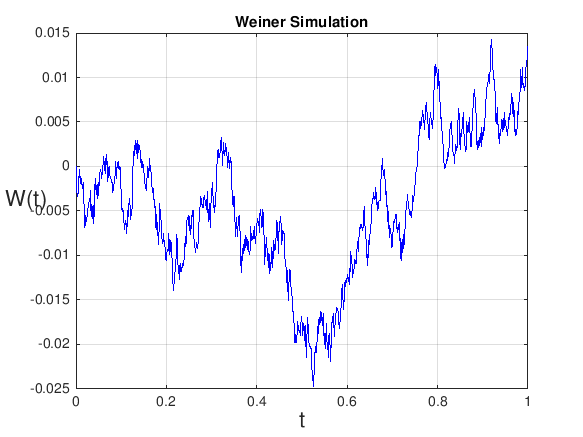

      
T = 1; N = 1000; dt = T/N;

dW = normrnd(0,0.001,[1,1000]);   % increments
W = cumsum(dW);                   % cumulative sum

plot([0:dt:T],[0,W],'b-')         % plot W against t
xlabel('t','FontSize',16)
ylabel('W(t)','FontSize',16,'Rotation',0)
grid on
title('Weiner Simulation')

#### Part 2:

mu=0;       %mu=mean of normal distribution
sig=sqrt(1);  %sig=variance of normal distribution
n=1000;T=10;    %T=total time length, N=number of iterations
alpha=2;        %alpha = given fixed point
DT=T/n;         %DT=small time interval
DX=SIGMA*sqrt(DT);      %DX=small displacement
p=.5*(1+(MU*sqrt(DT)/sig));q=1-p;
for i=1:1000
    A(i)=i*(T/n);  %A(i)=time
    if rand(1,1)<p
        Z(i)=DX;    %Z(i)=length of ith step
    else
        Z(i)=-DX;
    end
    if i==1
        W(i)=Z(i);   %W(i)=displacement of Wiener process
    else
        W(i)=W(i-1)+Z(i);
    end
    X(i)=W(i)+A(i);   %X(i)=displacement of process acc. to given
end
i=1;
while(X(i)<=alpha) 
        FPT=A(i);    %FPT=first passage time
        i=i+1;
    end
disp("first passage time for alpha=2")

first passage time for alpha=2


FPT

FPT = 0.5800

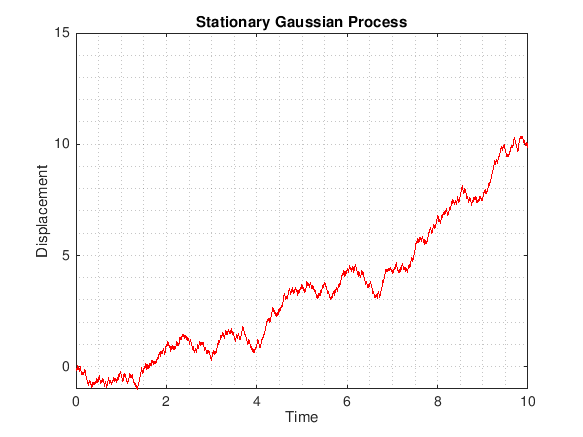

figure
plot(A,X,'r-')
grid minor
axis([0 10 -1 15])
xlabel('Time')
ylabel('Displacement')
title('Stationary Gaussian Process') 